%% =========================================================
%  VIBRATION ANALYSIS USING CWRU DATA (12 kHz DRIVE END)
%  File   : IR007_0.mat
%  Signal : X105_DE_time
% =========================================================

clc;
clear;
close all;

%% -------------------------------
% 1. LOAD DATA
% -------------------------------
data = load('IR007_0.mat');

x = data.X105_DE_time;   % Drive End vibration signal
rpm = data.X105RPM;      % Motor speed (RPM)

fs = 12000;              % Sampling frequency (Hz)

fprintf('Motor Speed = %.2f RPM\n', rpm);

Motor Speed = 1797.00 RPM


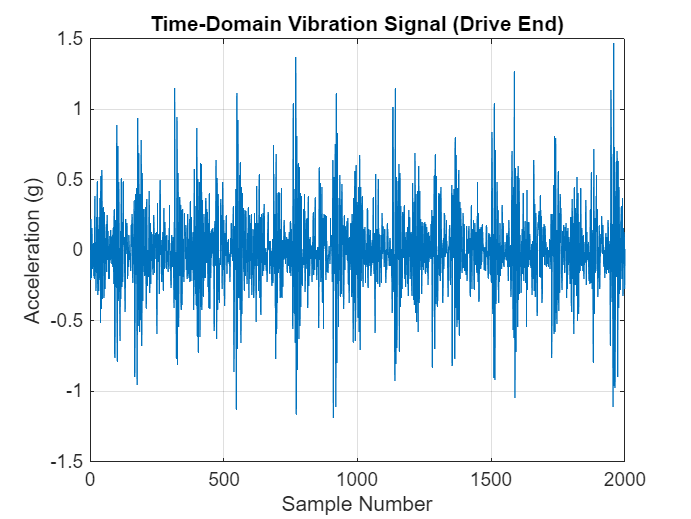


%% -------------------------------
% 2. PREPROCESSING
% -------------------------------
x = x - mean(x);         % Remove DC offset (gravity)

%% -------------------------------
% 3. TIME DOMAIN PLOT
% -------------------------------
figure;
plot(x(1:2000));
xlabel('Sample Number');
ylabel('Acceleration (g)');
title('Time-Domain Vibration Signal (Drive End)');
grid on;


%% -------------------------------
% 4. RMS CALCULATION
% -------------------------------
rms_val = rms(x);

fprintf('RMS Vibration = %.4f g\n', rms_val);

RMS Vibration = 0.2912 g


fprintf('RMS Vibration = %.4f m/s^2\n', rms_val * 9.81);

RMS Vibration = 2.8568 m/s^2


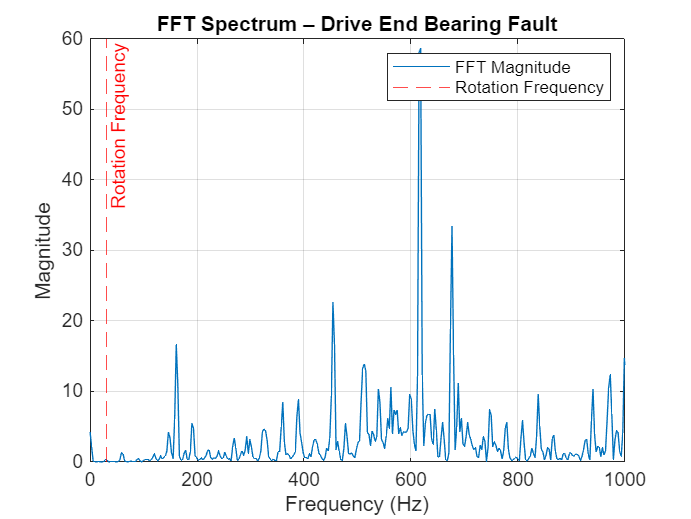


%% -------------------------------
% 5. FFT ANALYSIS
% -------------------------------
N = 4096;                % FFT size
window = hann(N);        % Hann window

X = fft(x(1:N) .* window);
mag = abs(X(1:N/2));
f = (0:N/2-1) * (fs / N);

figure;
plot(f, mag);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('FFT Spectrum – Drive End Bearing Fault');
grid on;
xlim([0 1000]);          % Focus on low frequencies

%% -------------------------------
% 6. ROTATIONAL FREQUENCY MARKER
% -------------------------------
fr = rpm / 60;           % Rotational frequency (Hz)
hold on;
xline(fr, 'r--', 'Rotation Frequency');
legend('FFT Magnitude', 'Rotation Frequency');


fprintf('Rotational Frequency = %.2f Hz\n', fr);

Rotational Frequency = 29.95 Hz


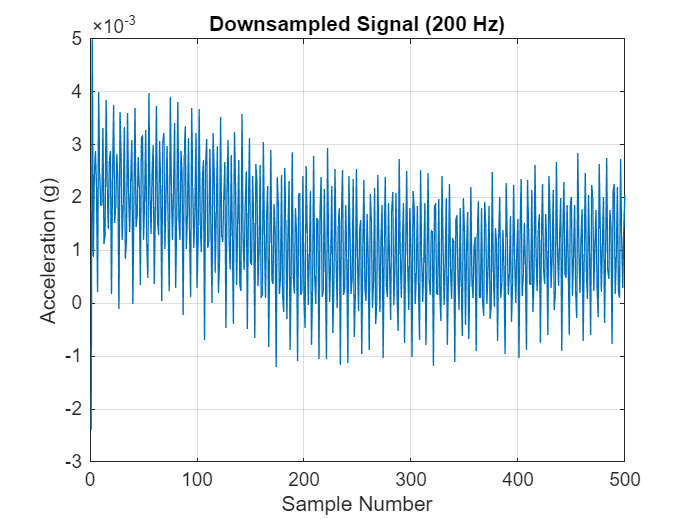


%% -------------------------------
% 7. OPTIONAL: DOWNSAMPLE FOR WEB USE
% -------------------------------
fs_web = 200;            % Target sampling rate for browser
x_ds = resample(x, fs_web, fs);

figure;
plot(x_ds(1:500));
xlabel('Sample Number');
ylabel('Acceleration (g)');
title('Downsampled Signal (200 Hz)');
grid on;


%% -------------------------------
% 8. SAVE CSV FOR WEB APP (OPTIONAL)
% -------------------------------
t_ds = (0:length(x_ds)-1)' / fs_web;
csv_data = [t_ds, x_ds];

writematrix(csv_data, 'IR007_0_downsampled.csv');

Error using writematrix (line 218)
Unable to open file 'C:\Users\kawin\Downloads\IR007_0_downsampled.csv' for writing:

Permission denied


disp('Downsampled CSV file saved: IR007_0_downsampled.csv');

%% -------------------------------
% END OF SCRIPT
% -------------------------------
